# Welcome To Your First MatLab Radar Simulation Tutorial!!

First of all I want to warn you that this is not going to be a normal, professional,borring simulation class. Instead, it will be about playing, having fun and learning in the process! 

So what are we waiting for and let's jump right into it, shall we?

Okay, let me refresh your memory a little bit about how radar works with the following picture.

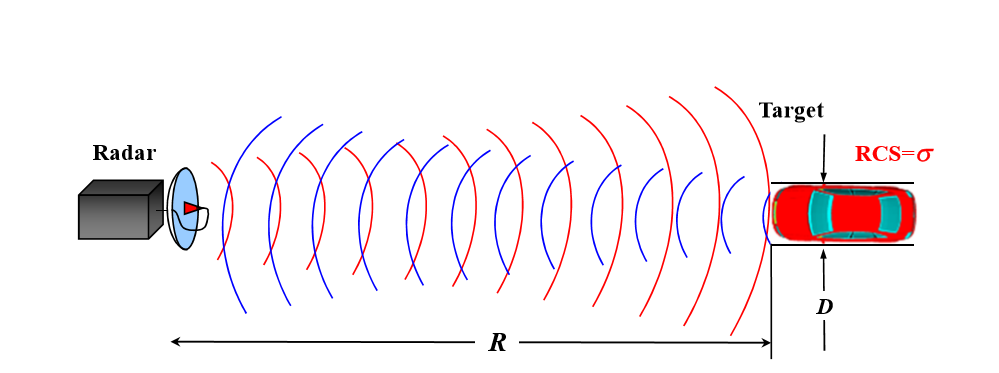

Really pretty isn't it?

- As you probably already know (or not) the basic concept consist in sending a RF Signal (Radio Frequency) to espace. 

- This transmitted Signal (known as Tx)  travels all the way until it reaches an object. This signal is represented with the color red.

- As a result the signal bounces back to the radar. This is known as the received signal (Blue). Or as you probably have heard Rx.

Does it sound familiar?..... Yes! It's similar to how bats identify objects but with the difference that here we use** electromagnetic radiation waves** instead of sound.

More simple cannot be, I believe. So don't be afraid and follow me in this adventure where you will learn to model your **OWN** radar system!

But before we start I want to ask you how well do you know the Fourier Transform?

I bet you've already seen it in math class. Most probably you have done all the long integration process whitout understanding why were you doing it and what was the purpose.

But believe it or not, it's a really cool tool in order to make things less complicated! (I know, that might sound ironic but just give me the chance to prove it to you)

So, in case you feel confident with it you can skip this step. But if you want to refresh a little bit feel free join us!.

## A short Review Of How The Fourier Transform Works

Don't worry about the code right now. I want you to concentrate on the signal we're going to generate, okay? 

clear all;
close all;

t        = linspace(0,4*pi,1256);
x_Square = square(t);

So imagine you have a really sexy good looking square wave signal.

**Square Waveform Signal**

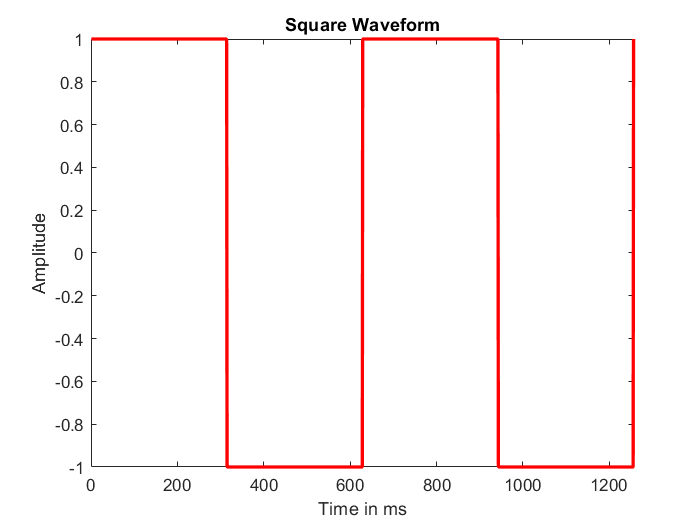

figure;
plot(x_Square,'r', 'LineWidth',2)
title('Square Waveform');
xlabel('Time in ms');
ylabel('Amplitude');
xlim([-0.001 1257]);

Beautiful isn't it?

Now let's think for a moment....is there any other way to reproduce that same square signal but using other signals instead?

Maybe using triangles function on top of each other? Or maybe a** bunch of sinus functions but added all together**?

 Do you think that is possible?

Well, guess what...the answer is hell yeah.

Let's check it with the following code!

**Let's create 3 different sinus signals and let's add them all together.**

x  = linspace(-2*pi,2*pi,1000); %Setting our time axis
y1 = sin(2*x + 15);             %First Signal
y2 = 3*sin(5*x + 23);           %Second Signal
y3 = 0.5*sin(x + 50);           %Third Signal
y4 = y1+y2+y3;                  %Sum of the 3 Signals

**Plotting the 3 differents signals and **

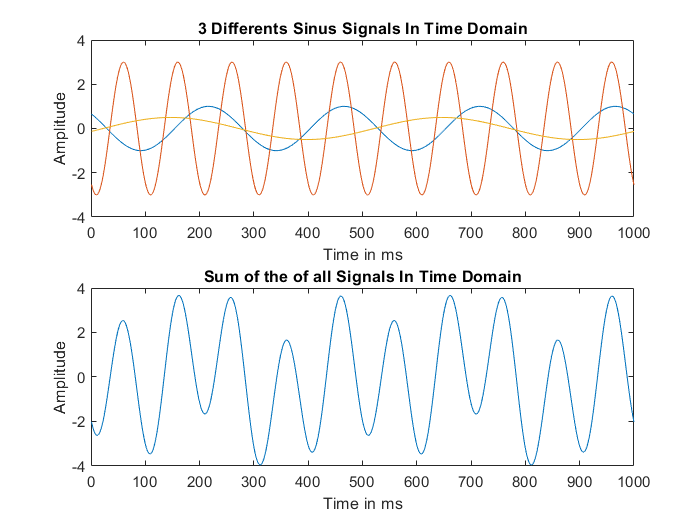

figure;
subplot(2,1,1);
plot(y1);hold on;
plot(y2);hold on;
plot(y3);
title('3 Differents Sinus Signals In Time Domain')
xlabel('Time in ms');
ylabel('Amplitude');
subplot(2,1,2);
plot(y4);
title('Sum of the of all Signals In Time Domain')
xlabel('Time in ms');
ylabel('Amplitude');

- As you can see above we plotted 3 different sinus signals. Each with different amplitudes, frequencies and phase shifts. (Top image)

- At the bottom you can see the sum of the 3 different signals.

-  If you don't believe me then take a look at the time when is 0. 

- There you will see the blue signal with an **amplitude** of maybe **0.5**.....the yellow signal with an amplitude of -**0.1** and the orange one with an amplitude of **-2.4**

- Feel free to use the zoom if you want. You can find it if you put your pointer in the corresponding image. Then clicking at the top right corner the (+) option. Finally just zoom it. 

- If you cannot find it make sure to run the skript first.

- In case you did a fail don't panic. Just go back to the top corner and click the option that looks like a home.

- So if you add all those amplitudes together: 0.5 + (-0.1) +(-2.4) = -2

And guess what?....That's exactly what we see at the bottom image at time = 0!.

So the million dollar question.....Does the sum of all signals look like a square wave to you?

I don't know you guys, but for me that does not look like a square wave at all. It looks quite disgusting if you ask me.

Well, now let's try something new.....

Let's use this magic formula that I found when I applied the Fourier Transform to my original square waveform.

**Fourier Transform Equation of a Square Waveform**


$$y\left(t\right)=\mathrm{sin}\left(t\right)+\frac{\mathrm{sin}\left(3t\right)}{3}+\frac{\mathrm{sin}\left(5t\right)}{5}+\frac{\mathrm{sin}\left(7t\right)}{7}+\frac{\mathrm{sin}\left(9t\right)}{9}+\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp +\frac{\mathrm{sin}\left(2n-1\right)}{n}$$


At first this might look like gibberish, but what do you think is gonna happen when we plot it?

Well, let's find it out!

Like I said before, don't worry about the code yet. The reason why I am doing this is to make sure you understand what's going on with the Fourier transform. 

But if You are still curious, let me know and I'll explain it to you later line by line.

**Setup the Time Grid**

Sample_Frequency       = 100;                               %[Hz]
Sample_Time            = 1/Sample_Frequency;                %[s]
Measurement_Time       = 10;                                 %[s]
Time_Grid              = 0:Sample_Time:Measurement_Time-Sample_Time;                                %[s]
Num_Of_Samples         = Sample_Frequency*Measurement_Time; %[]

**Number of Harmonics**

Num_Of_Harmonics = 2;                                 %Number Of Harmonics <==== Hey right over here!

**Saving our values in Y**

y = zeros(Num_Of_Harmonics,Num_Of_Samples);         

for Count_Of_Harmonics = 1:Num_Of_Harmonics
    index = 1;
    for Time_Grid_Count = 0:Sample_Time:Measurement_Time-Sample_Time
            p          =  2*Count_Of_Harmonics-1;
            y(Count_Of_Harmonics,index) = sin(p*Time_Grid_Count)/p;      
            index      = index + 1;      
    end
end
Y = sum(y,1);                                           %Adding all the rows together and make it one single with all the signals in it.

**Now let's finally plot our signal.**

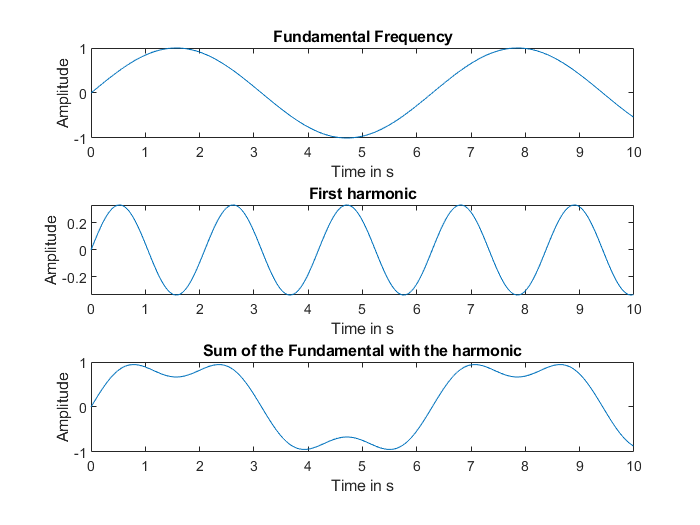

figure;
subplot(3,1,1);
plot(Time_Grid, y(1,:));
xlabel('Time in s');
ylabel('Amplitude');
title('Fundamental Frequency');
subplot(3,1,2);
plot(Time_Grid, y(2,:))
xlabel('Time in s');
ylabel('Amplitude');
title('First harmonic');
subplot(3,1,3);
plot(Time_Grid, Y);
xlabel('Time in s');
ylabel('Amplitude');
title('Sum of the Fundamental with the harmonic');

- Here we are repeating the same process one more time! 

- We are adding the first signal (top plot) with the second (middle plot).

- Then plotting the result at the bottom. (It's exactly the same thing as we did before)

- So if you add the **Fundamental Frequency** with the **First Harmonic** (don't worry about this names, I'll explain it to you later) does it look like a square wave?

- I mean.... I guess you can see more or less the square shape if you close one eye?....or maybe both?

- So let's do the following...**.I want you to go back to the code, but this time increase the number of harmonics to 5.**

- Now Run the MatLab Skript (Press "Ctrl + Enter" on the keyboard)

It kind of looks better isn't? So what did we do?

If you take a look back at our magical formula...


$$y\left(t\right)=\sin \left(t\right)+\frac{\sin \left(3t\right)}{3}+\frac{\sin \left(5t\right)}{5}+\frac{\sin \left(7t\right)}{7}+\frac{\sin \left(9t\right)}{9}+\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp +\frac{\sin \left(2n-1\right)}{n}$$


- You notice that there are only sinuses with some factors. (like 1/3....1/5..inside the sinus function is 3t....5t... and so on)

- Each** sinus function is adding with each other**. Just like I explained you before.

- The first element you see is $\mathrm{sin}\left(t\right)\ldotp$This is exactly what you see in the diagramm as **Fundamental Frequency.**

- The second element is $\frac{\mathrm{sin}\left(3t\right)}{3}$. Again, this is what you see as **First Harmonic.**

- And if you continue....the next one would be $\frac{\sin \left(5t\right)}{5}$, which would be refered as **Second Harmonic**. 

In short, what you did was to create more of these functions and you added them all! Which made your function looked more like a square! Cool isn't?

If that's not clear enough take a look at this image!

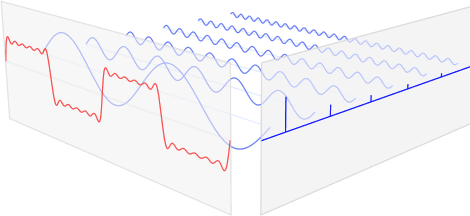

Here you can see the same idea. 

- Each sinus function has their own amplitude, phase shift and **FREQUENCY.**

- And if you add them all together you will get the function you wanted to recreate.

- After all **every single function** can be represented as a combinations of multiple sinus waveforms (Just like in the picture)!

- It is worth mentioning that there is a sinus function with a bigger amplitude than the rest.  

- This one is the **most important** sinus function from all of them. Why is that? Well, Basically its **Frequency** carries a lot of information! Which then describes more precisely your Square Waveform Signal (Hence, The Fundamental Frequency).

I want you to keep that in mind. Believe me, it will make things clear like water when we go to **Frequency Domain**.

## **Frequency Domain**

So far we have only considered the **Time Domain. **You see..... everytime we plotted our signals you could easily notice the **time** **in seconds** along the x-axis. The same goes for the **amplitude** in the y-axis.

Now I want to introduce you to our second best friend, the **Frequency Domain. **Here you will notice that we are not talking anymore about time in the x-axis but **Frequencies in Hz**. The same applies for the y-axis....Instead of Amplitude we now have the **Power in dB**.

In case you don't remember what it is or how does it look like, let me show it to you.

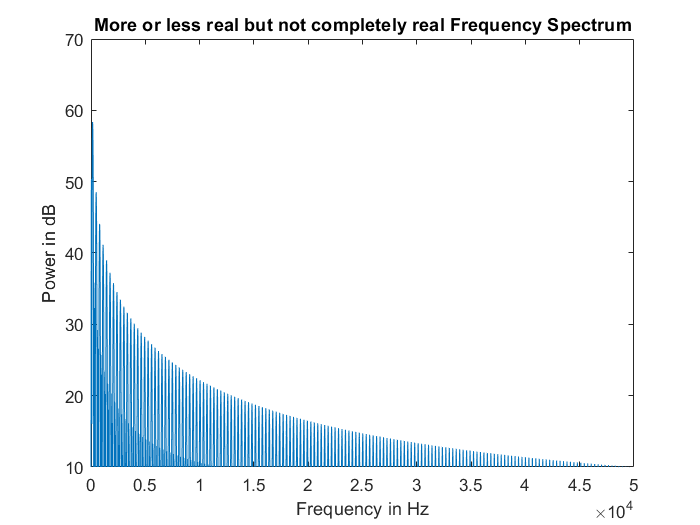

Power = 20*log10(abs(fft(x_Square,1e5)));
Frequency_bins  = 0:length(Power)-1;
Frequency = Frequency_bins*1e5/length(Power);
figure;
subplot(1,1,1);
plot(Frequency,Power);
xlabel('Frequency in Hz');
ylabel('Power in dB');
xlim([0 length(Power)/2]);
title('More or less real but not completely real Frequency Spectrum')
xlim([0 50000])
ylim([10 70])

What you are looking at it is kwon as the **Frequency Spectrum**. Guess why?...Yes!! Because now we are looking at the Frequencies along the x-axis instead of the time!

I just want to remind you: This is the** Frequency Spectrum of a Square waveform!! **So do not take for granted that other Waveform signals (like triangles, pulses,...) have the same shape.

But hey! What does that even mean? And why do we see this peaks?

- As I mentioned it before, a sinus signal has a particular amplitude, phase shift and **FREQUENCY**.

- So you can imagine the Frequency x-axis as if you have a lot of sinus signals.

- And where you read 1 Hz would represent a sinus signal of 1 hz. 

- Where you read 2 Hz would represent a sinus signal of 2 hz and so on.  

Now....what about the peaks?

- Well, first of all the higher the peak, the more power that corresponding frequency has.

- For example: Frequencies that are closer to 0 tend to have a higher peak (at least in this case of the Square Waveform).

- Now, I want you to memorize the next statement:  **The power represents how much information that corresponding Frequency Signal has. **

- For Example: above we can see that signals with l**ower Frequencies** have more information than the ones with higher Frequencies. Since they have a higher power.

#### So now is when the fun part begins!!

Do you remember  when I talked about the Fundamental Frequency? That it was the Frequency that gave us a lot of information about the square wavefrom signal? 

And remember, **the more power you have, the more information you get.**

So, I ask you...

**Question:** From all the peaks you see in the Frequency Spectrum.....which one would you say it represents the Fundamental signal?

**Answer:** Yes! the closest one to 0!! Because it has the highest peak power. Therefore carries most of the information.

And now if you have to guess one more time...

**Question:** Which one do you think is the first harmonic?

**Answer:** Yes!! the one that follows the fundamental!! Since is the second one that carries most of the information.

So I want you to take another look at this picture you are already familiar.

- If you see the diagram that correspond to the blue lines, you will notice that it has more or less the shape of the frequency Spectrum we plotted!!!

- (You see 5 peaks....the first peak has the highest power.....is followed by multiple peaks with less power each time)

- Well,  both of them are the exact same thing actually.

- The first frequency corespond to the fundamental Frequency, which has the has the greatest power. Followed by the other harmonics with less power.

- Those are represented in the first 2 signals you see in front.

- That's why you will see that the longer we go along the x-axis, the higher the frequency of the sinus signal.

- That's why when you are looking at the Frequency spectrum **the power decreases the higher the Frequency.**

I hope it's all clear!

The reason why I want you to understand how Frequency Domain works is because we will use it to analyze everything....literally everything.

## Frequency Spectrum for Range Estimation

Now that you feel a little bit more confortable with Fourier and Frequency Domain..... I want to show you a picture of what we are gonna be looking at in the near future.

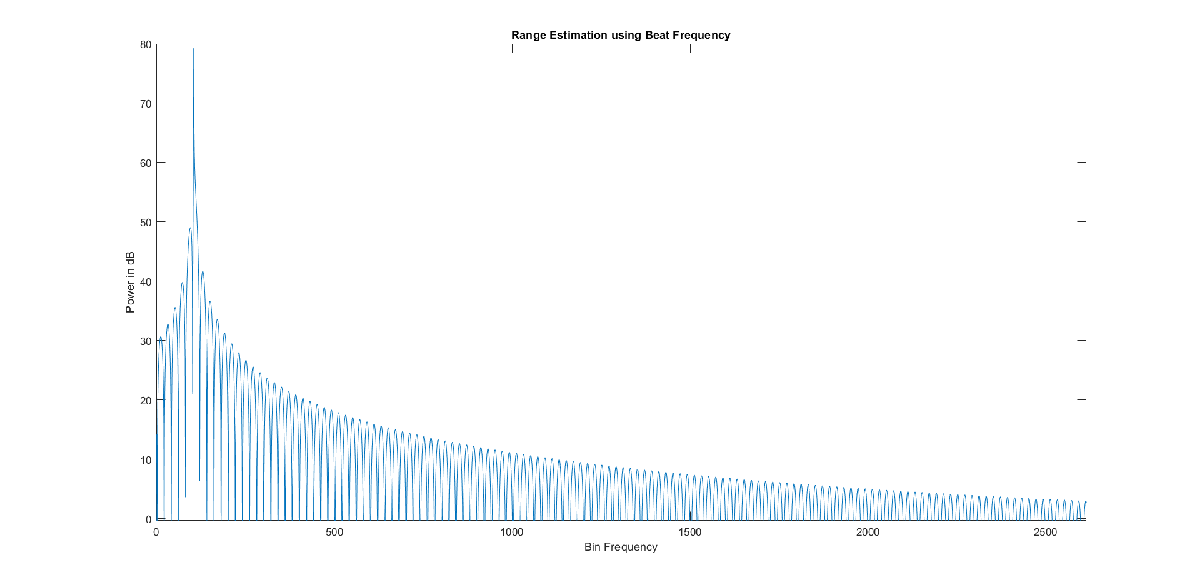

The plotted diagram you see on top is an ideal representation of a range estimation using the beat Frequency.

As you are already familiar with.....The y-axis represents the power in dB and the x-axis should represent the frequency isn't?

but hold on a little bit! Here we are looking at the **Bin Frequency **and **not** at the normal** Frequency **along the x-axis.

I Just want you to get familiar with this term "Bin Frequency", since most of our analyzed signals would be represented this way.

**Question:** But what is a Bin Frequency and what does even represent?

To be honest it may seem a little confusing at first but it's not!

The plot you see above is no longer a Fourier transform but a **Discrete Fourier Transform**.

If you are not familiar with this term, you can imagine it as if you just took a little piece of the signal each time. (Instead of taking the whole signal)

You probably don't understand what I mean but look at the following chart!

**Number of Samples**

figure
Number_Of_Samples = 25;   %Here!!!!

**Plotting Discrete Signal**

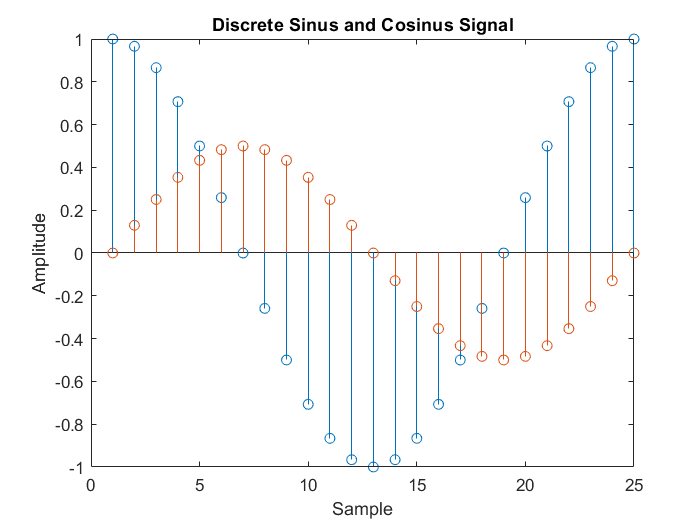

X = linspace(0,2*pi,Number_Of_Samples)';
Y = [cos(X), 0.5*sin(X)];
stem(Y);
title('Discrete Sinus and Cosinus Signal');
xlabel('Sample');
ylabel('Amplitude');

- Here you can see 1 sinus signal and 1 cosinus signal.

- But we are just taking small bites of the signal as you can see. 

- But hey! Even though we might miss some data between each bite (the blank space), we are able to distinguish the shape of the sinus signal and the cosinus signal. cool isn't?

- Now, this 'Bite' is more popular known as a **Sample**.

- (Remember we are looking at the x-axis.)

- You'll notice that the more samples you have, the more it looks like a sinus function.

- And the blank space between each Sample is known as **Sample Time [s]**.

- Now Imagine that the duration of this **signal is 1 second long**.

- Next: I want you to divide the number of samples by one second.

In this case is         $\frac{25\;\mathrm{Samples}}{1\;s}=25\;\mathrm{Hz}$

- That means that your **Sample Frequency is 25 Hz! **

- With other words, you are taking 25 samples every second!

- Now, I want you to increase the number of samples (to 200) in the code from above and tell me what do you see! (Remember to press "Ctrl + Enter" in order to run the code)

- You should be seeing a sinus and cosinus signal that you are more used to see (A smoother continuos signal)

So back to our Frequency Spectrum for range estimation.

- Take a Iook at the next formula. 


$$\textrm{Frequency}=\frac{\left(\textrm{Frequency}\;\textrm{Bin}*\textrm{Sample}\;\textrm{Frequency}\right)}{\textrm{Number}\;\textrm{of}\;\textrm{Samples}\;\textrm{of}\;\textrm{the}\;\textrm{Fourier}\;\mathrm{Transform}}$$


- **Here we are converting from bin Frequencies to normal Frequencies!**

- Here the **Sample Frequency** describes one more time how fast did you take 'Bites'. 

- The higher the Sample Frequency, the more information you will get. 

- Since the space between each sample will be smaller.

- Now, the number of Samples you divide it is not the same Number of samples as you played before.

- Instead is describing how many samples you took **From the actual infinitely long Fourier Transform. **

**For example: If your number of samples down below would be infinity, then you are doing a normal Fourier Transform. **$\frac{\left(\mathrm{Frequency}\;\mathrm{Bin}*\mathrm{Sample}\;\mathrm{Frequency}\right)}{\infty }$

- However, if you decide to take just 1000 pieces of that infinitely long Fourier.....You will be getting a **Discrete Fourier! **

- More or less in a similar way like the plotted sinus and cosinus signal you already played with.

- If you notice, the higher the number of samples you put, the smoother the signal it looks.

- So, **one single Frequency bin correspond to exactly one sample of the Fourier. **That means... If you have 1000 Samples, then you also have 1000 frequency bins.

Later on we are gonna talk about why the number of samples is **IMPORTANT**. But for now just keep that in mind.

If you take a look one more time at the range Estimation using beat Frequency plot....You will observe that there is an especific **bin Frequency** that has the** highest power peak. **(Bin Frequency 100 more or less)

That my Friends..... Is the corresponding bin Frequency that will tell us how far my target is.

After everything we have seen, I think we're ready to start designing our model!!!